syms x2dot x4dot x1 x2 x3 x4 u

x1dot = x2;
x3dot = x4;
% Define the equations
eq1 = ((0.27 + 4.32*10^(-5)/0.0004))*x2dot + ((0.27*0.0004 + 4.32*10^(-5)))*x4dot/0.02 - 0.27*x1*x4^2 == (0.27*9.81*sin(x3));
eq2 = (0.27*(x1)^2 + 4.32*10^(-5) + 14.025*10^(-2))*x4dot + (2*0.27*x2*x1 + (0.49)^2)*x4 + (10^(-3) *(0.49)^2)*x3 +  ((0.27*0.0004 + 4.32*10^(-5)))*x2dot/0.02 -(0.27*9.81*x1*cos(x3)) == u*(0.49*cos(x3));

% Solve the equations for x and y
sol = solve([eq1, eq2], [x2dot, x4dot]);

% Extract the separate equations for x and y
eq_x2dot = sol.x2dot;
eq_x4dot = sol.x4dot;
Ja = jacobian([x1dot, eq_x2dot, x3dot, eq_x4dot], [x1, x2, x3, x4]);
A = subs(Ja, {x1, x2, x3, x4, u}, {0, 0, 0, 0, 0});
A_matrix = vpa(A)

$$A\_matrix = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ -0.37800231194074585511603465092137 & 0 & 7.0147371686269233059274629246388 & 0.034265245251245169257884969866811\\ 0 & 0 & 0 & 1.0\\ 18.900115597037290752313968305761 & 0 & -0.37971557420330811326463544522379 & -1.7132622625622582812816037264368 \end{array}\right)$$

Jb = jacobian([x1dot, eq_x2dot, x3dot, eq_x4dot], u);
B = subs(Jb, {x1, x2, x3, x4, u}, {0, 0, 0, 0, 0});
B_matrix = vpa(B)

$$B\_matrix = \left(\begin{array}{c} 0\\ -0.069929071941316671954867285442471\\ 0\\ 3.4964535970658332271053137274221 \end{array}\right)$$

c = [1 0 0 0; 0 0 1 0];
A = double(A);
B = double(B);

## 1

s = tf('s');
cx = [1 0 0 0];
P_slow = [-2+2*i; -2-2*i; -2.5+8*i; -2.8-5*i];
P_fast = [-20+2*i; -30+8*i; -25-i; -29-3*i];
k_slow = acker(A, B, P_slow);

k_fast = acker(A, B, P_fast);

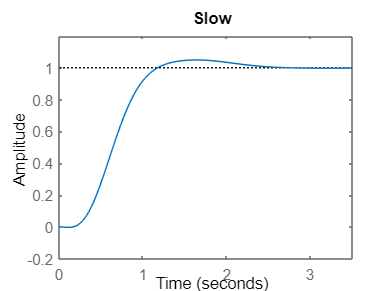

p_s = -inv(cx*inv((A-B*k_slow))*B);
p_f = -inv(cx*inv((A-B*k_fast))*B);

G_slow = cx*inv((s*eye(4) - A+B*k_slow))*B*p_s;
G_fast = cx*inv((s*eye(4) - A+B*k_fast))*B*p_f;

step(G_slow)
title('Slow')

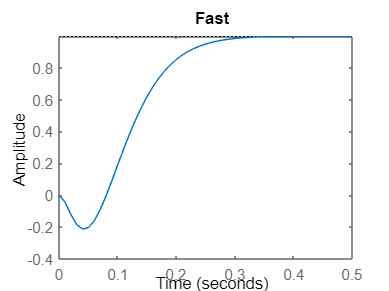

step(G_fast)
title('Fast')

## 2

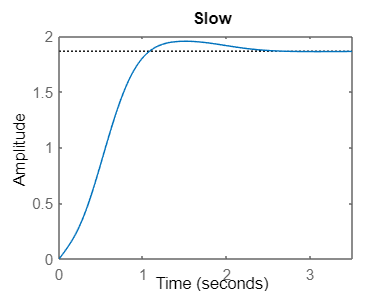

d = [1; 1; 0; 2];
G_slow = cx*inv((s*eye(4) - A+B*k_slow))*B*p_s + cx*inv((s*eye(4) - A+B*k_slow))*d;
G_fast = cx*inv((s*eye(4) - A+B*k_fast))*B*p_f + cx*inv((s*eye(4) - A+B*k_fast))*d;

step(G_slow)
title('Slow')

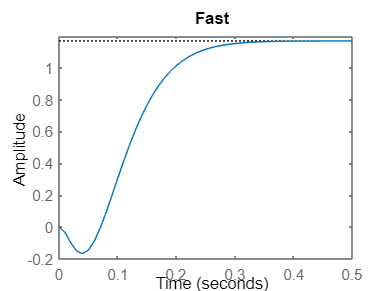

step(G_fast)
title('Fast')

## 3

A_bar = zeros(5);
A_bar(1:4, 1:4) = A;
A_bar(5, 1:4) = -cx;
B_bar = zeros(5, 1);
B_bar(1:4, 1) = B;
cx_bar = zeros(1, 5);
cx_bar(1, 1:4) = cx;
Co = ctrb(A_bar,B_bar);
det_co = vpa(det(Co))

$$det\_co = -179788.4381448448984883725643158$$


P_slow3 = [-2+2*i; -2-2*i; -2.5+8*i; -2.8-5*i; -3-4*i];
P_fast3 = [-20+2*i; -30+8*i; -25-i; -29-3*i; -27];
k_slow3 = acker(A_bar, B_bar, P_slow3);

k_fast3 = acker(A_bar, B_bar, P_fast3);

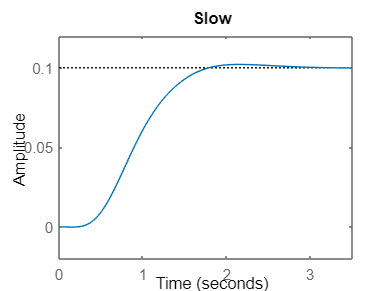


k1_slow = k_slow3(1, 1:4);
k1_fast = k_fast3(1, 1:4);
k2_slow = k_slow3(1, 5);
k2_fast = k_fast3(1, 5);

R = zeros(5,1);
R(5,1) = 1;

G_slow = cx_bar*inv((s*eye(5) - A_bar+B_bar*k_slow3))*R*0.1;
G_fast = cx_bar*inv((s*eye(5) - A_bar+B_bar*k_fast3))*R*0.1;
step(G_slow)
title('Slow')

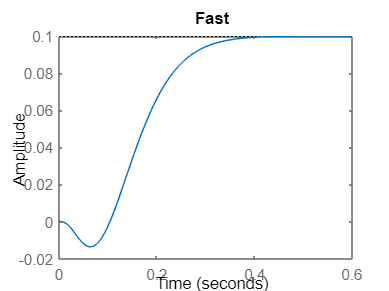

step(G_fast)
title('Fast')

## 4

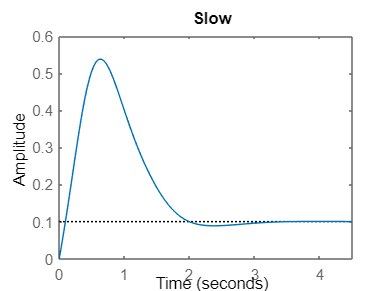

d = [1; 1; 0; 2; 0];

G_slow = cx_bar*inv((s*eye(5) - A_bar+B_bar*k_slow3))*R*0.1 + cx_bar*inv((s*eye(5) - A_bar+B_bar*k_slow3))*d;
G_fast = cx_bar*inv((s*eye(5) - A_bar+B_bar*k_fast3))*R*0.1 + cx_bar*inv((s*eye(5) - A_bar+B_bar*k_fast3))*d;

step(G_slow)
title('Slow')

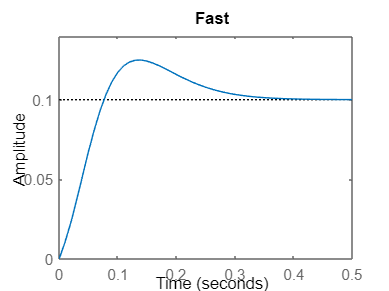

step(G_fast)
title('Fast')

## 5


L = place(A', cx', [-3.5,-3,-4,-3.8])';
A_estimator = A - L*cx;


## 6

disp(A)

         0    1.0000         0         0
   -0.3780         0    7.0147    0.0343
         0         0         0    1.0000
   18.9001         0   -0.3797   -1.7133



eigenvalues = eig(A);
disp(eigenvalues);

   2.9896 + 0.0000i
  -3.8454 + 0.0000i
  -0.4288 + 3.3669i
  -0.4288 - 3.3669i





F = [-1, 0, 0; 0, -2, 0; 0, 0, -4];
disp(F)

    -1     0     0
     0    -2     0
     0     0    -4



eigenvalues_F = eig(F);
disp(eigenvalues_F);

    -4
    -2
    -1




L_lyapanov = [5;10;15];   
disp(L_lyapanov)

     5
    10
    15




Co_6 = ctrb(F,L_lyapanov);
det_co_6 = vpa(det(Co_6))

$$det\_co\_6 = -4500.0$$



T = sym('T', [3, 4]);

equation = T*A - F*T == L_lyapanov*cx;

solution_T = solve(equation, T);


disp('Solution for T:');

Solution for T:


disp(solution_T);

    T1_1: 18517166528752599398676334714552320/1469966779228668868360473791401917091
    T2_1: -211669286555934234699480986372014080/1411338390568639583732549931877628579
    T3_1: 1269317022016024461103191594834591744/57822968062781437439961967585060729
    T1_2: -18517166528752599398676334714552320/1469966779228668868360473791401917091
    T2_2: 105834643277967117349740493186007040/1411338390568639583732549931877628579
    T3_2: -317329255504006115275797898708647936/57822968062781437439961967585060729
    T1_3: 8865386775864499734277151661574437605/47038936935317403787535161324861346912
    T2_3: -3596370294100765487889401009950835995/22581414249098233339720798910042057264
    T3_3: 17111930660418777559333503811800829917/1850334978009005998078782962721943328
    T1_4: 387527640254447051447083780737597440/1469966779228668868360473791401917091
    T2_4: 771250744144959129402925580980060160/1411338390568639583732549931877628579
    T3_4: -229092501425126754726132485996937216/578229680627


numeric_det = subs(det([cx; T]), solution_T);
disp(numeric_det);

$$-\frac{3163803660900108163720568585887148086238487023635436696377681370739705028270053994457116018287485701324800}{6313721984826908454684370012815854116310667625053408760546709891349220496071385375524005352033345939004699}$$

var = vpa(numeric_det)

$$var = -0.50109961580559589219502633260586$$


numeric_TB = subs(T*B, solution_T);
disp(numeric_TB);

$$\left(\begin{array}{c} \frac{10850138400003471908171384256477744545}{11759734233829350946883790331215336728}\\ \frac{10756966080886697048264758479588380065}{5645353562274558334930199727510514316}\\ -\frac{6230566082651758563858894932771627463}{462583744502251499519695740680485832} \end{array}\right)$$

TB = vpa(numeric_TB)

$$TB = \left(\begin{array}{c} 0.92265166748333179564128462304589\\ 1.9054548067229697010863948395033\\ -13.469055401754250342212554588803 \end{array}\right)$$

TB = double(TB)

TB =     0.9227
    1.9055
  -13.4691



CTinv = inv(double([cx; subs(T, solution_T)]));

disp('Inverse of [cx; T]:');

Inverse of [cx; T]:


disp(CTinv);

    1.0000         0         0         0
    5.2867    8.8261   -6.3556   -0.2893
    0.6517    5.3919   -2.9868   -0.0532
   -0.2611    0.3603    1.8316    0.0242



CTinv = double(CTinv)

CTinv =     1.0000         0         0         0
    5.2867    8.8261   -6.3556   -0.2893
    0.6517    5.3919   -2.9868   -0.0532
   -0.2611    0.3603    1.8316    0.0242
